# **Visión Artificial - Sistemas de Visión Artificial**

# **Práctica 3. Segmentación de imágenes (II)**

**Autor(es): Joseph Principe Pajuelo Condori**

**Fecha: 23/10/2026**

Este mlx contiene la parte de la práctica 3 relacionada con la segmentación basada en bordes y con el uso de la transformada de Hough para detectar rectas y circunferencias. También se incluye un ejercicio de segmentación basada en regiones mediante la transformada watershed.

**Ejercicios propuestos:**

**1. Transformada watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realice una segmentación utilizando la transformada watershed. Analice si se produce sobresegmentación. En caso afirmativo, intente reducirla mediante preprocesado morfológico.

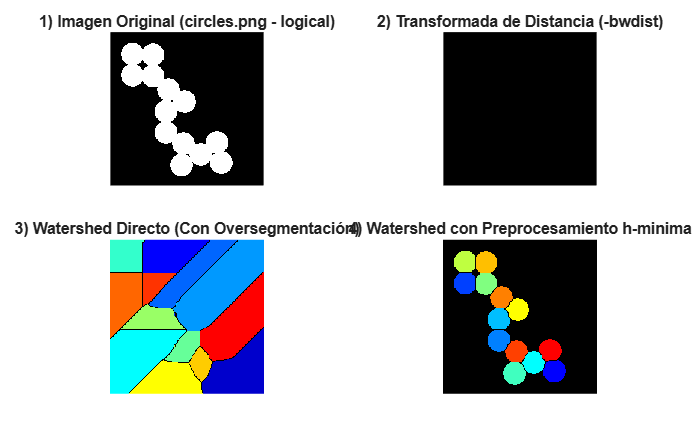

%% Practica 3 Parte 2: Transformada Watershed

clearvars -except I_rgb I_gray; close all;
BW = imread('circles.png');
% Calcula la transforama de distancia (distancia euclidiana hacia el pixel negro mas cercano)
D = -bwdist(~BW);
% Algoritmo watershed
L_watershed_directo = watershed(D);
% Filtrado de h-minima (solucion sobresegmentacion)
h = 1.5;
% Suprime todos los valles pocos profundos
D_modificado = imhmin(D, h);
L_watershed_limpio = watershed(D_modificado);
L_watershed_limpio(~BW) = 0;

figure('Name', 'Segmentación por Transformada Watershed');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; 
imshow(BW); 
title('1) Imagen Original (circles.png - logical)');

nexttile; 
imshow(D); 
title('2) Transformada de Distancia (-bwdist)');

nexttile; 
imshow(label2rgb(L_watershed_directo, 'jet', 'k', 'shuffle')); 
title('3) Watershed Directo (Con Oversegmentación)');

nexttile; 
imshow(label2rgb(L_watershed_limpio, 'jet', 'k', 'shuffle')); 
title('4) Watershed con Preprocesamiento h-minima');

**2. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

- Detecte los bordes mediante Canny. Utilice controles deslizantes para modificar los umbrales y/o σ, visualice el efecto de las distintas configuraciones y comente cómo afecta cada parámetro al resultado. **                                                                                                                                                                      σ desviacion estandar del filtro Gaussiano, controla el nivel de suavizado previo de la imagen. Si es muy alto, el algoritmo no filtra el ruido y si es muy alto la imagen se desenfoca demasiado. Con respecto a los umbrales, si es muy alto, solo detectará los fragmentos con mayor contraste de la moneda y si es bajo, ayuda a conectar los bordes debiles al borde fuerte.**

- Intente conectar los bordes separados por pequeños huecos mediante dilatación (`imdilate`). Visualice el resultado.

- Rellene los contornos obtenidos.

- Segmente los distintos objetos, etiquetándolos con *bwlabel *y muestre el resultado final.

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel' ``y` compare los resultados Canny - Sobel. Justifique las diferencias.                                                              **Canny genera lineas continuas, delgadas y mucho más limpias. Sobel genera bordes más gruesos, ruidosos y frecuentemente rotos o abierto. Al rellenar con imfill, canny suele dar el número exacto de monedas, mientras que sobel falla.                                                                                                                             Canny incluye pasos adicionales que Sobel no tiene: Un suavizado Gaussiano inicial, supresión de no máximos y el umbralizado por histéresis. Sobel simplemente calcula una derivada espacial y aplica un único umbral global, lo que lo hace propenso a dejar contornos abiertos si la iluminación cambia.**

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.                                                                                                             **Sin realizar la dilatación, la función imfill no logra rellenar la mayoría de las monedas, dejándolas idénticas o con pequeños puntos blancos sueltos. Al realizar la dilatación, casi el 100% de monedas se rellena por completo como discos blancos sólidos.**

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.                                                                                         **Al utilizar un disco, las monedas conservan su forma geométrica perfectamente circular despúes de rellenadas. Al utilizar un cuadrado, las monedas adquieren bordes ligeramente pixeleados en las diagonales, perdiendo su rendodez natural.**

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.                                                                                                                    **Los objetos segmentados mediante dilatación pura terminan siendo más grandes en tamaño que las monedas reales de la imagen. Por el contrario, al aplicar un cierre morfológico, las monedas mantienen su tamaño y dimensiones originales exactas en el mapa final.**

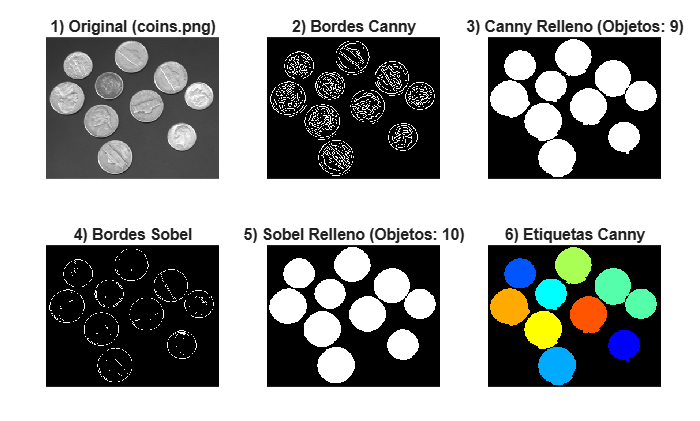

%% Segmentacion basada en bordes

clearvars -except I_rgb I_gray;

I_coins = imread('coins.png');
if size(I_coins, 3) == 3
    I_coins = rgb2gray(I_coins);
end

% Deteccion con CANNY, dilatacion, relleno y etiquetado
sigma_val = 1.2;
[BW_canny, thresholds] = edge(I_coins, 'canny', [], sigma_val);

SE_canny = strel('disk', 2);
BW_canny_dil = imdilate(BW_canny, SE_canny);
BW_canny_filled = imfill(BW_canny_dil, 'holes');
% Etiquetar
[L_canny, num_canny] = bwlabel(BW_canny_filled);
[BW_sobel, threshold_sobel] = edge(I_coins, 'sobel');
% Deteccion de paralela de sobel
BW_sobel_dil = imdilate(BW_sobel, SE_canny);
BW_sobel_filled = imfill(BW_sobel_dil, 'holes');
[L_sobel, num_sobel] = bwlabel(BW_sobel_filled);
% Pruebas
BW_canny_sin_dil = imfill(BW_canny, 'holes');
SE_square = strel('square', 3);
BW_canny_dil_square = imdilate(BW_canny, SE_square);
BW_canny_dil_square_filled = imfill(BW_canny_dil_square, 'holes');

BW_canny_close = imclose(BW_canny, SE_canny);
BW_canny_close_filled = imfill(BW_canny_close, 'holes');

figure('Name', 'Segmentación por Bordes: Canny vs Sobel');
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_coins);          title('1) Original (coins.png)');
nexttile; imshow(BW_canny);         title('2) Bordes Canny');
nexttile; imshow(BW_canny_filled);  title(['3) Canny Relleno (Objetos: ', num2str(num_canny), ')']);
nexttile; imshow(BW_sobel);         title('4) Bordes Sobel');
nexttile; imshow(BW_sobel_filled);  title(['5) Sobel Relleno (Objetos: ', num2str(num_sobel), ')']);
nexttile; imshow(label2rgb(L_canny, 'jet', 'k', 'shuffle')); title('6) Etiquetas Canny');

**3. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, detecte y represente los 7 segmentos de recta más largos de la imagen **'despacho1.jpg'**. 

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre los segmentos detectados.                                                                                                                                                                                                 **Estos dos parámetros controlan cómo la función reconstruye segmentos de recta reales a partir de los pixeles de borde alineados en el espacio de Hough. FillGap (distancía máxima de separación) define la distancía máxima que puede haber entre dos pixeles de borde alineados para que se consideren parte de la misma linea recta. Si es muy alto, cualquier pequeña interrupción del borde hará que una linea continua se fragmente en múltiples segmentos cortos e independientes. Si es muy alta, el algoritmo unirá segmentos que estaban separados.                                                                                                                               MinLlength (longitud mínima del segmento), define el umbral de longitud mínima que debe medir un segmento para ser aceptado y devuelto por la función. Si es muy bajo, aparecerán decenas de segmentos diminutos e irrelevantes causado por el ruido. Si es muy alto, el algoritmo descartará las rectas pequeñas y medianas.**

- Calcule el número de picos `size(P,1)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?                                                        **Generalmente son diferentes, siendo habitualmente el número de lineas mayor que el numero de picos. Un pico en la matriz de Hough representa una recta matemática infinita que acumula una gran cantidad de pixeles. Sin embargo, la función de houghliness analiza los pixeles reales sobre la imagen que pertenecen a esa trayectoria infinita. Si a lo largo de esa misma recta matemática infinita hay varios objetos independientes separados generará un segmento de recta independiente para cada uno. Por lo tanto, un solo pico en el espacio de Hough puede dar origen a múltiples segmentos de linea en el espacio de la imagen, rompiendo la simetría entre picos y lineas detectadas. **

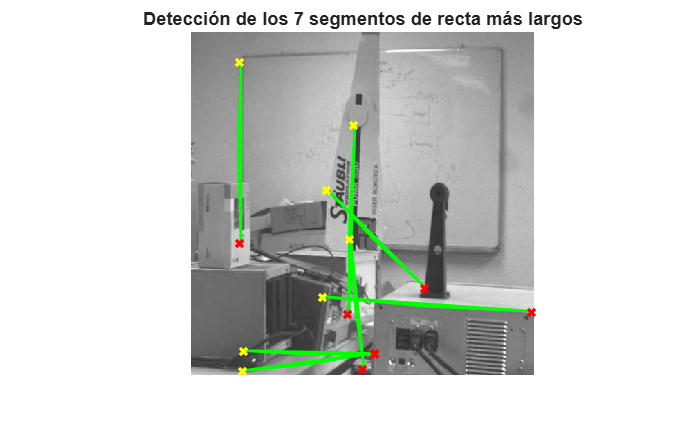

%% Deteccion de rectas con transformada de Hough

I_despacho = imread('despacho1.jpg');
if size(I_despacho, 3) == 3
    I_despacho_gray = rgb2gray(I_despacho);
else
    I_despacho_gray = I_despacho;
end

% Deteccion de bordes con canny
BW_despacho = edge(I_despacho_gray, 'canny');
% La transformada de Hough
[H, theta, rho] = hough(BW_despacho);
% Buscando picos
P = houghpeaks(H, 30, 'Threshold', ceil(0.3 * max(H(:))));
% Extraer lineas con houghlines
fill_gap_val = 20; 
min_len_val = 30;
lines = houghlines(BW_despacho, theta, rho, P, 'FillGap', fill_gap_val, 'MinLength', min_len_val);
% Ordenar las lineas de mayor a menor
lengths = arrayfun(@(l) norm(l.point1 - l.point2), lines);
[~, sorted_idx] = sort(lengths, 'descend');

if length(sorted_idx) >= 7
    top7_lines = lines(sorted_idx(1:7));
else
    top7_lines = lines; % Si hay menos de 7, coge todas las disponibles
    warning('Se encontraron menos de 7 líneas con los parámetros actuales.');
end

figure('Name', 'Transformada de Hough: 7 Segmentos más largos');
imshow(I_despacho);
hold on;
for k = 1:length(top7_lines)
    xy = [top7_lines(k).point1; top7_lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 3, 'Color', 'green');

    % Marcar el inicio y fin del segmento
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
end
title(sprintf('Detección de los %d segmentos de recta más largos', length(top7_lines)));
hold off;



%% Análisis de tamaño: Picos vs Líneas
num_peaks = size(P, 1);
num_lines = length(lines);

fprintf('--- ANÁLISIS DE HOUGH ---\n');

--- ANÁLISIS DE HOUGH ---


fprintf('Número de picos en el acumulador (size(P,1)): %d\n', num_peaks);

Número de picos en el acumulador (size(P,1)): 30


fprintf('Número de segmentos de recta obtenidos (length(lines)): %d\n', num_lines);

Número de segmentos de recta obtenidos (length(lines)): 79


**4. Detección de circunferencias utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y represente el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

- Resalte la célula más grande pintándola de un color diferente.

- ¿Cuántas células ha encontrado?                                                                                                                                                                                                              **El algoritmo ha detectado un total de 30 células. Este resultado corresponde al número de elementos devueltos por la función imfindcircles dentro del vecto de radios length(radii), utilizando un rango de búsqueda de 7 a 20 pixeles de radio y una sensibilidad de 0.92.**

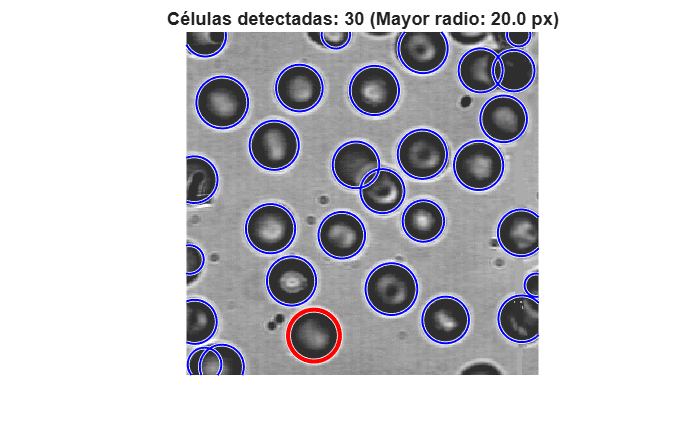

%% Deteccion de circunferencia con hough

clearvars -except I_rgb I_gray;

I_blood = imread('blood1.tif');
if size(I_blood, 3) == 3
    I_blood = rgb2gray(I_blood);
end
% Definir el rango de radios de las celulas
minRadius = 7;
maxRadius = 20;

% Transformada de hough circular
[centers, radii, metric] = imfindcircles(I_blood, [minRadius, maxRadius], ...
    'ObjectPolarity', 'dark', ...
    'Sensitivity', 0.92, ...
    'Method', 'TwoStage');

% Identificar la celula mas grande
if ~isempty(radii)
    [max_radius, idx_max] = max(radii);
    center_max = centers(idx_max, :);
else
    error('No se han encontrado células con los parámetros actuales.');
end

figure('Name', 'Transformada de Hough Circular: Células en blood1.tif');
imshow(I_blood);
hold on;

% Todas las células encontradas en color azul
viscircles(centers, radii, 'EdgeColor', 'b', 'LineWidth', 1.2);

% Resaltando la celula mas grande de color rojo
viscircles(center_max, max_radius, 'EdgeColor', 'r', 'LineWidth', 2.5);

title(sprintf('Células detectadas: %d (Mayor radio: %.1f px)', length(radii), max_radius));
hold off;


fprintf('--- RESULTADOS HOUGH CIRCULAR ---\n');

--- RESULTADOS HOUGH CIRCULAR ---


fprintf('Número total de células encontradas: %d\n', length(radii));

Número total de células encontradas: 30


fprintf('Coordenadas de la célula más grande: [X=%.1f, Y=%.1f], Radio=%.1f\n', ...
    center_max(1), center_max(2), max_radius);

Coordenadas de la célula más grande: [X=99.0, Y=235.0], Radio=20.0
